clear all
close all

FEA = FEAfunctions;

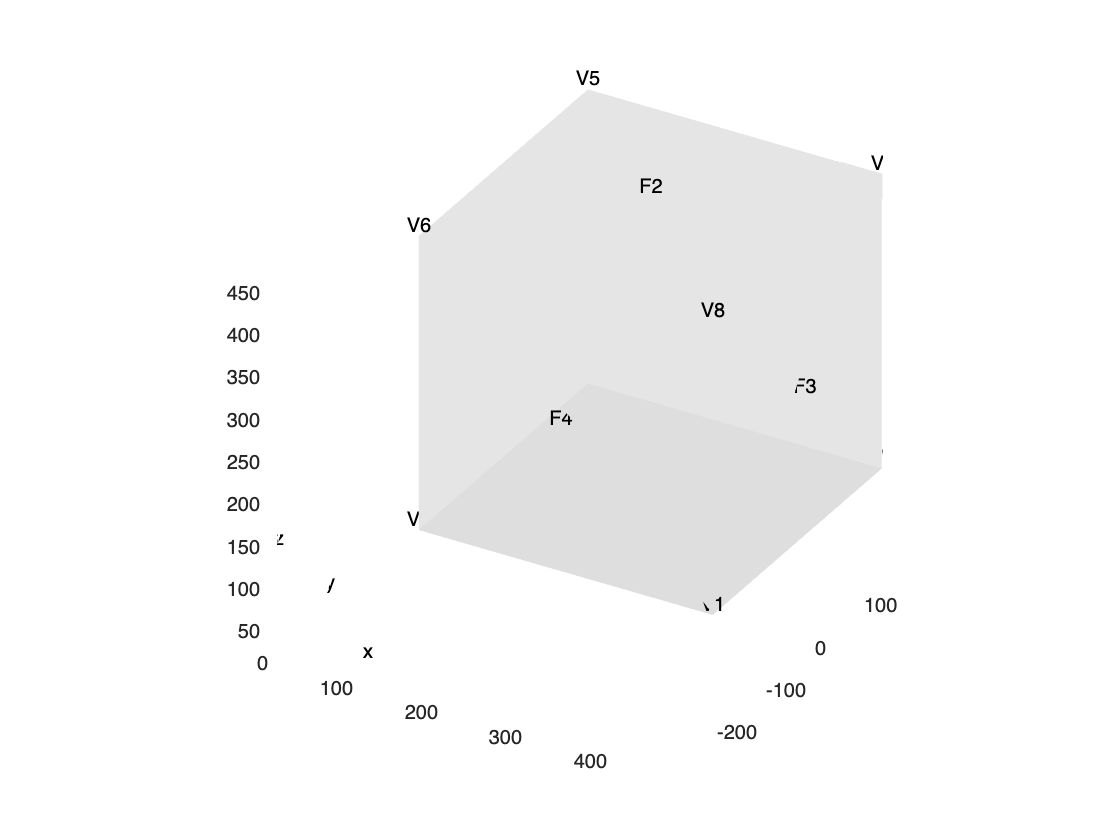

smodel = FEA.pdeModel('./cube.stl');

mesh = FEA.createMesh(smodel);

E = 4.107E9;
nu = 0.3;
fixedVertices = [];
fixedFaces = [[3,5]];
loadedFaces = [[2]];
Faceforces = [[0;0;-1000]];
loadedVertices = [[]];
Vertexforces = [[]];
[Rs, stressColors] = FEA.applyFEA(smodel,E,nu,fixedVertices,fixedFaces,loadedVertices,Vertexforces,loadedFaces,Faceforces);

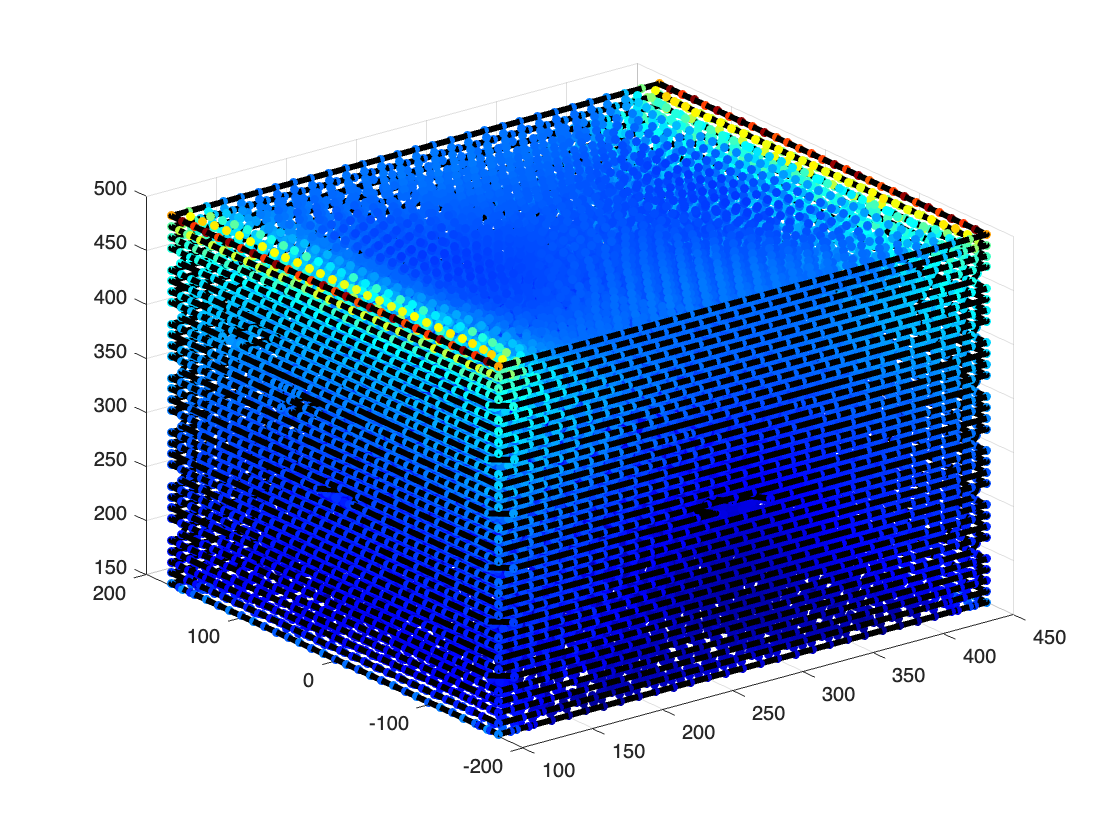

layers = 1×36 struct array with fields:
    X
    Y
    stresses


layerHeight = 10;
layers = FEA.generateAllLayers(smodel,mesh,Rs,stressColors,layerHeight,false)

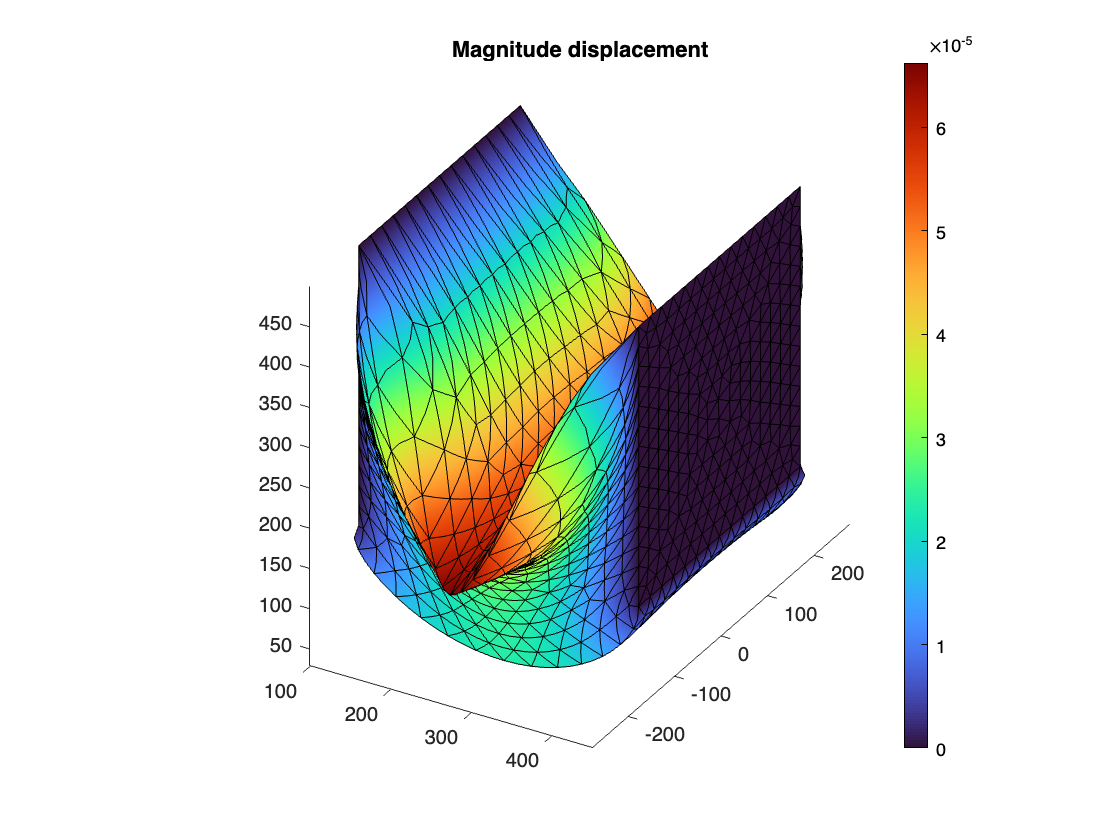

% Data to visualize
meshData = Rs.Mesh;
nodalData = Rs.Displacement.Magnitude;
deformationData = Rs.Displacement;

% Create PDE result visualization
resultViz3 = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",5253293.8897, ...
    "MeshVisible",true, ...
    "Title","Magnitude displacement", ...
    "ColorLimits",[0 6.619e-05]);


% Clear temporary variables
clearvars meshData nodalData deformationData

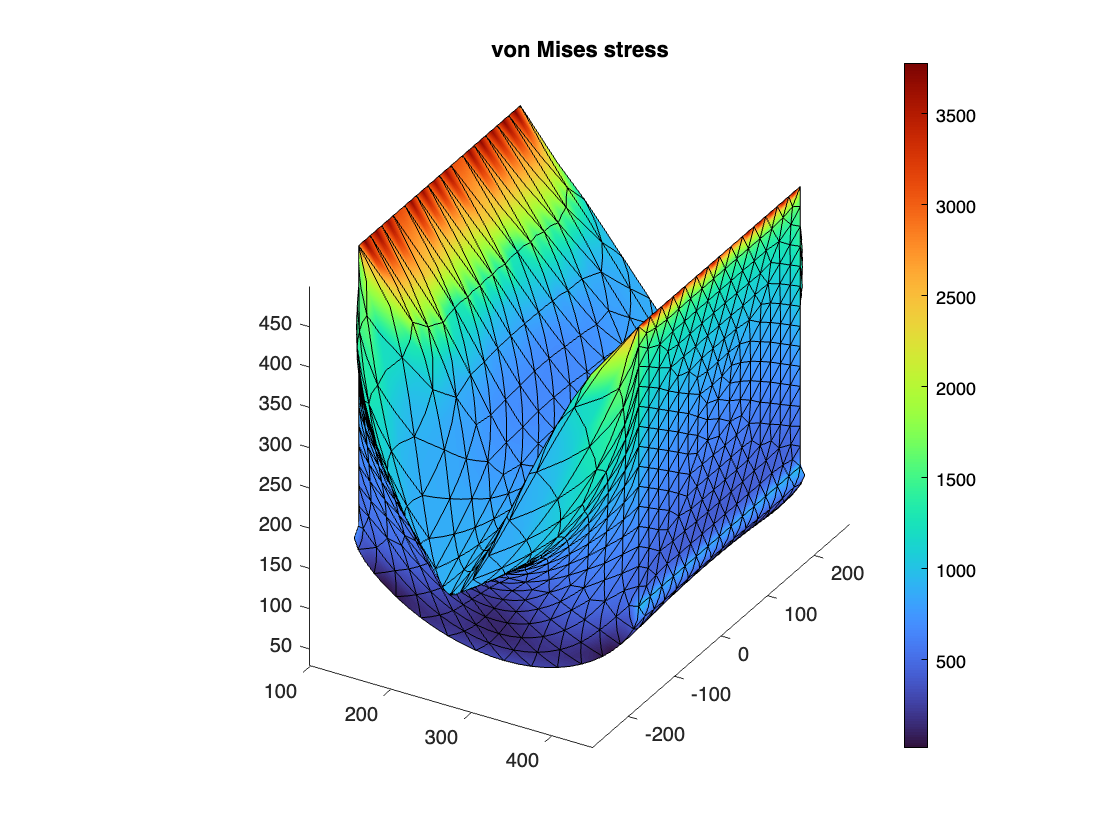

% Data to visualize
meshData2 = Rs.Mesh;
nodalData2 = Rs.VonMisesStress;
deformationData2 = Rs.Displacement;

% Create PDE result visualization
resultViz4 = pdeviz(meshData2,nodalData2, ...
    "DeformationData",deformationData2, ...
    "DeformationScaleFactor",5253293.8897, ...
    "MeshVisible",true, ...
    "Title","von Mises stress", ...
    "ColorLimits",[15.47 3778]);


% Clear temporary variables
clearvars meshData2 nodalData2 deformationData2

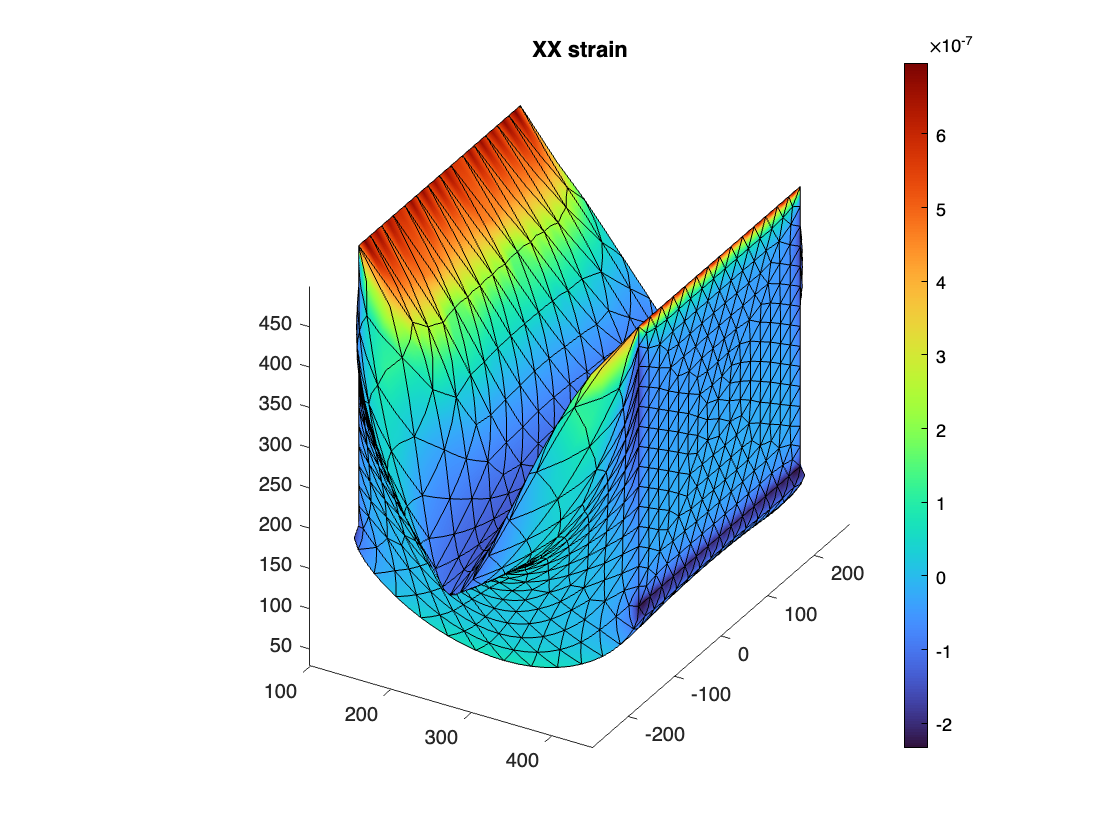

% Data to visualize
meshData3 = Rs.Mesh;
nodalData3 = Rs.Strain.exx;
deformationData3 = Rs.Displacement;

% Create PDE result visualization
resultViz5 = pdeviz(meshData3,nodalData3, ...
    "DeformationData",deformationData3, ...
    "DeformationScaleFactor",5253293.8897, ...
    "MeshVisible",true, ...
    "Title","XX strain", ...
    "ColorLimits",[-2.336e-07 6.962e-07]);


% Clear temporary variables
clearvars meshData3 nodalData3 deformationData3